clc;
close all;
clear;
engine_Type = 1;    % 0=Single spool | 1=Double spool
turbo_Fan = 0;      % 0=Yes | 1=No
T0 = 10 + 273.16;    % Ambient temperature
titles = "";

if engine_Type == 0 %single spool
    %afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool\Single_spool.png');
    if T0 <= 253.16
        afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool\Single_spool_-40_-20.png');
        titles = "Single spool (-40 < ambient < -20)"
    end
    if T0 >= 253.17 && T0 <= 273.16
        afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool\Single_spool_-19_0.png');
        titles = "Single spool (-20 < ambient < 0)"
    end
    if T0 >= 273.17 && T0 < 293.16
        afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool\Single_spool_1_20.png');
        titles = "Single spool (0 < ambient < 20)"
    end
    if T0 >= 293.17
        afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool\Single_spool_21_40.png');
        titles = "Single spool (ambient > 20)"
    end
end

if engine_Type == 1 %double spool
    if turbo_Fan == 1 %no turbo fan
        %afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool.png');
        if T0 <= 253.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool\Double_spool_-40_-20.png');
            titles = "Double spool (-40 < ambient < -20)"
        end
        if T0 >= 253.17 && T0 <= 273.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool\Double_spool_-19_0.png');
            titles = "Double spool (-20 < ambient < 0)"
        end
        if T0 >= 273.17 && T0 < 293.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool\Double_spool_1_20.png');
            titles = "Double spool (0 < ambient < 20)"
        end
        if T0 >= 293.17
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool\Double_spool_21_40.png');
            titles = "Double spool (ambient > 20)"
        end
    end
    if turbo_Fan == 0 %turbo fan
        %afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool_Turbo_fan.png');
         if T0 <= 253.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool_turbo_fan\Double_spool_turbo_fan_-40_-20.png');
            titles = "Double spool turbo fan (-40 < ambient < -20)"
        end
        if T0 >= 253.17 && T0 <= 273.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool_turbo_fan\Double_spool_turbo_fan_-19_0.png');
            titles = "Double spool turbo fan (-20 < ambient < 0)"
        end
        if T0 >= 273.17 && T0 < 293.16
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool_turbo_fan\Double_spool_turbo_fan_1_20.png');
            titles = "Double spool turbo fan (0 < ambient < 20)"
        end
        if T0 >= 293.17
            afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool_turbo_fan\Double_spool_turbo_fan_21_40.png');
            titles = "Double spool turbo fan (ambient > 20)"
        end
    end
end

titles = "Double spool turbo fan (0 < ambient < 20)"

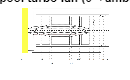


figure;
imshow(afbeelding);
title(titles);